# Create and Customize 3-D Point and Line Plots 

`plot3` creates 3-D point or line plots

## Create Data

Use simple sine and cosine functions in a helper function to generate vectors of points in 3-D space that form a helix

[t,x,y] = createData(1);

## Basic 3-D Line Plot

Plot a 3-D Helix using the `plot3` function

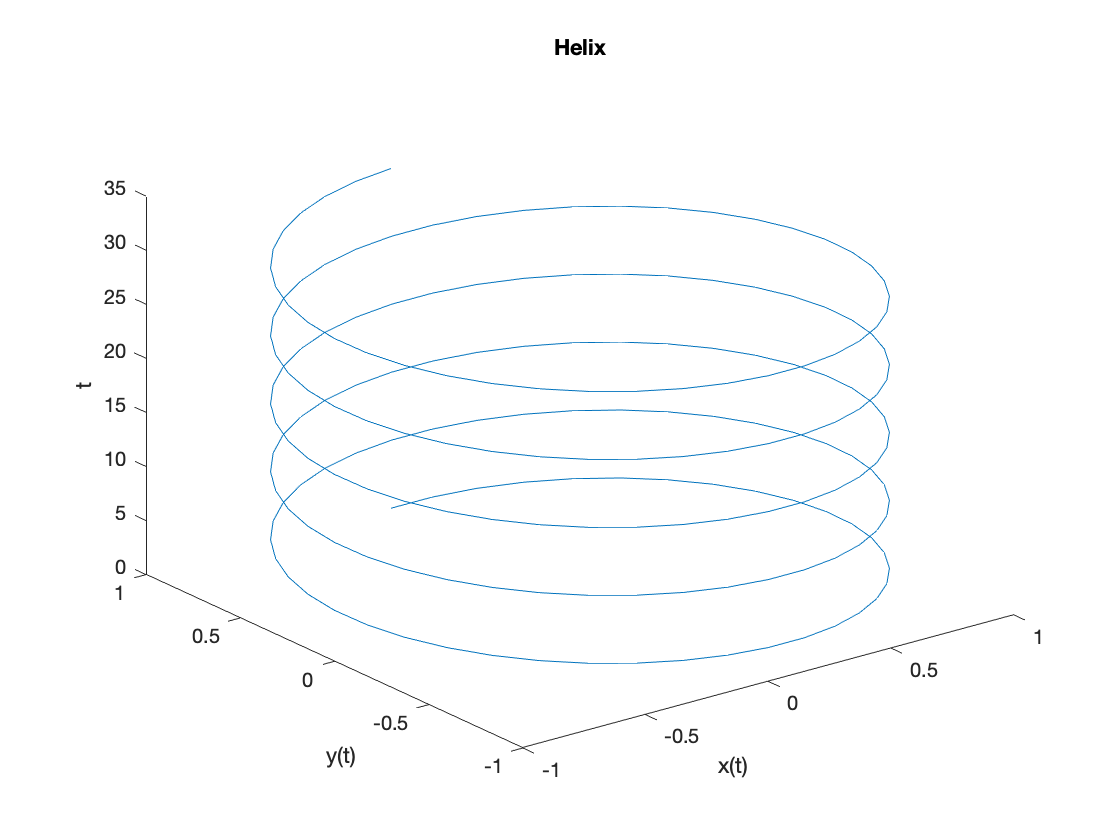

plot3(x,y,t)
title("Helix")
xlabel("x(t)")
ylabel("y(t)")
zlabel("t")

## Customization

### Customize Line and Marker

Specify the line type, line color and marker type when creating a plot by using a vector of line specification characters in the *LineSpec *input argument into `plot3`. The *LineWidth* property can be specified using a Name, Value pair to improve line visibility.

LineType = '--';

LineType = '--'

LineColor = 'b';

LineColor = 'b'

MarkerType = 's';

MarkerType = 's'

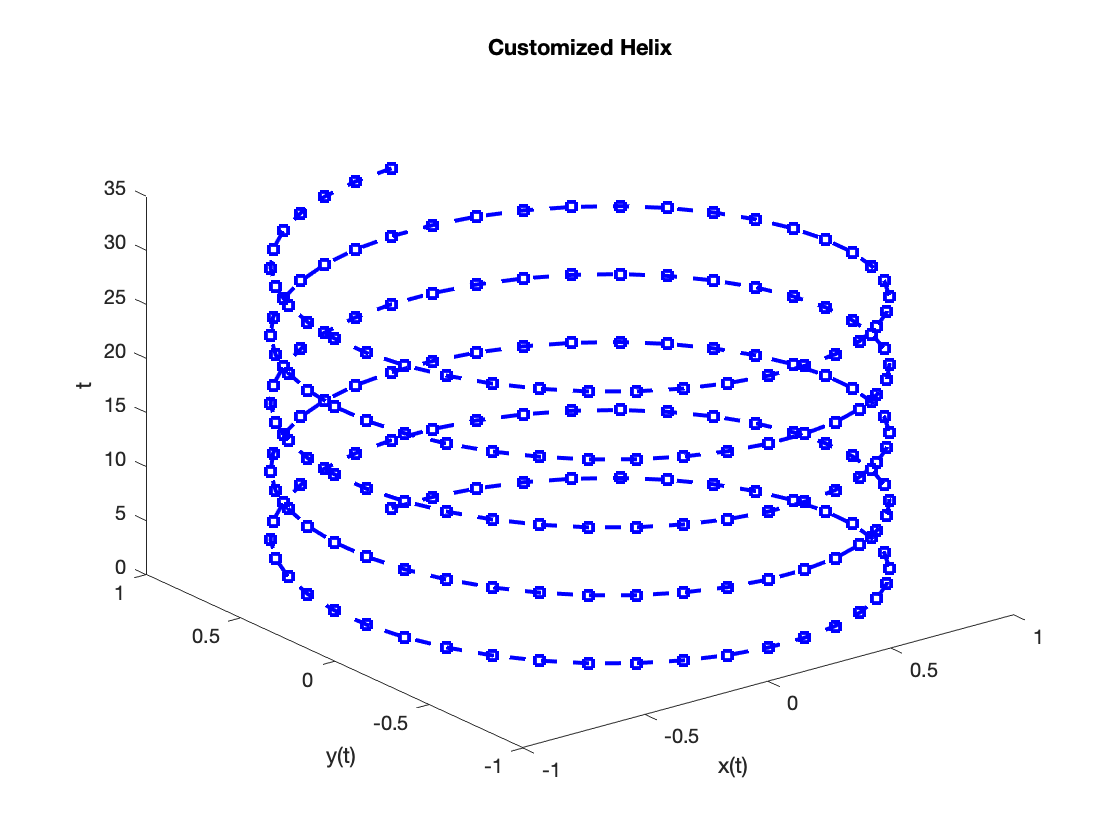

LineWidth = 2;

p = plot3(x,y,t,...
    [LineType LineColor MarkerType],... % Specify line and marker customizations
    "LineWidth",LineWidth);             % Specify line width
xlabel("x(t)")  
ylabel("y(t)")
zlabel("t")
title("Customized Helix")

### Specify Target Axes

Generate a helix with more spirals and plot on axes side-by-side for visual comparison using the tiledlayout function.

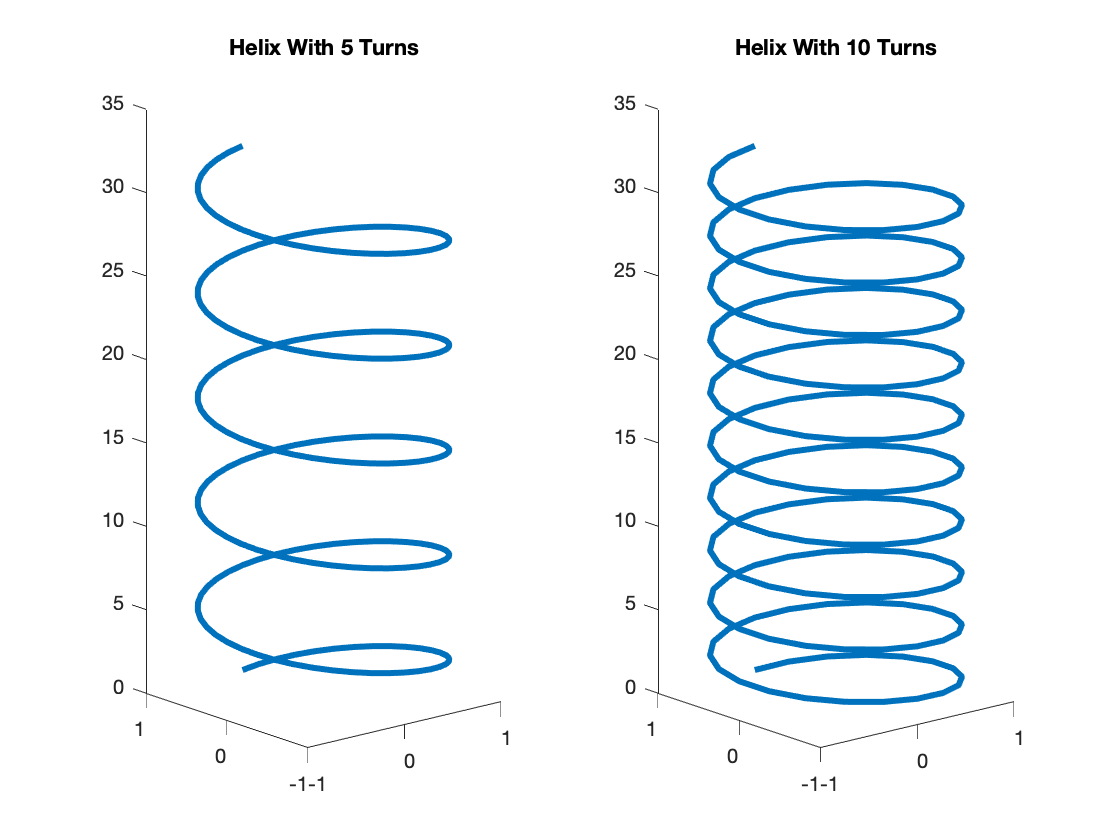

figure
tiledlayout(1,2)
[t,x1,y1] = createData(2);

% Left plot
ax1 = nexttile;
p1 = plot3(ax1,x,y,t,"LineWIdth",3);
title(ax1,"Helix With 5 Turns")
view([-40 7])                           % Rotate figure on axis 1 to see different view coordinates

% Right plot
ax2 = nexttile;
p2 = plot3(ax2,x1,y1,t,"LineWidth",3);
title(ax2,"Helix With 10 Turns")
view([-40 7])                           % Rotate figure on axis 2 to see different view coordinates

## **Additional Information**

### **Get All Line Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Line, uncomment the following code. View or modify these properties using dot notation.

% get(p)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[plot3](https://www.mathworks.com/help/matlab/ref/plot3.html)

### Helper Function

This function generates t, x and y data with the following relationship: $x=\sin \left(n*t\right),y=\cos \left(n*t\right)$.

function [t,x,y] = createData(n)
    t = 0:pi/20:10*pi;
    x = sin(n*t);
    y = cos(n*t);
end

Copyright (c) 2021, The MathWorks, Inc.